clear all
clc
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
file_namewalk = 'walkingRTK.bag';
file_pathwalk = fullfile('/Users','jakobringberg','Desktop','LINUX_SHARING','lab2bags',file_namewalk);

file_nameoc = 'occludedRTK.bag';
file_pathoc = fullfile('/Users','jakobringberg','Desktop','LINUX_SHARING','lab2bags',file_nameoc);

file_nameop = 'openRTK.bag';
file_pathop = fullfile('/Users','jakobringberg','Desktop','LINUX_SHARING','lab2bags',file_nameop);

bag_walk = rosbag(file_pathwalk);
bag_op = rosbag(file_pathop);
bag_oc = rosbag(file_pathoc);

bSel_walk = select(bag_walk,'Topic','/gps');
bSel_op = select(bag_op,'Topic','/gps');
bSel_oc = select(bag_oc,'Topic','/gps');

msgStructs_walk = readMessages(bSel_walk,'DataFormat','struct');
msgStructs_walk{1};

msgStructs_op = readMessages(bSel_op,'DataFormat','struct');
msgStructs_op{1};

msgStructs_oc = readMessages(bSel_oc,'DataFormat','struct');
msgStructs_oc{1};

%%%%%%%%%%%%%%%%%%%%%%

Time_walk = cellfun(@(m) double(m.Header.Stamp.Sec),msgStructs_walk);
NorthingPoints_walk = cellfun(@(m) double(m.UtmNorthing),msgStructs_walk);
EastingPoints_walk = cellfun(@(m) double(m.UtmEasting),msgStructs_walk);
avg_north_walk = mean(NorthingPoints_walk);
avg_east_walk = mean(EastingPoints_walk);

NorthingPoints_walk_dev = NorthingPoints_walk-avg_north_walk;
EastingPoints_walk_dev = EastingPoints_walk-avg_east_walk;

Alt_walk = cellfun(@(m) double(m.Altitude),msgStructs_walk);
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Time_op = cellfun(@(m) double(m.Header.Stamp.Sec),msgStructs_op);
NorthingPoints_op = cellfun(@(m) double(m.UtmNorthing),msgStructs_op);
EastingPoints_op = cellfun(@(m) double(m.UtmEasting),msgStructs_op);
avg_north_op = mean(NorthingPoints_op);
avg_east_op = mean(EastingPoints_op);
centroid_op = ([avg_north_op,avg_east_op]);

NorthingPoints_op_dev = NorthingPoints_op-avg_north_op;
EastingPoints_op_dev = EastingPoints_op-avg_east_op;

Alt_op = cellfun(@(m) double(m.Altitude),msgStructs_op);

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Time_oc = cellfun(@(m) double(m.Header.Stamp.Sec),msgStructs_oc);
NorthingPoints_oc = cellfun(@(m) double(m.UtmNorthing),msgStructs_oc);
EastingPoints_oc = cellfun(@(m) double(m.UtmEasting),msgStructs_oc);
avg_north_oc = mean(NorthingPoints_oc);
avg_east_oc = mean(EastingPoints_oc);
centroid_oc = ([avg_north_oc,avg_east_oc]);

NorthingPoints_oc_dev = NorthingPoints_oc-avg_north_oc;
EastingPoints_oc_dev = EastingPoints_oc-avg_east_oc;

Alt_oc = cellfun(@(m) double(m.Altitude),msgStructs_oc);
%%%%%%%%%%%%%%%%%%%%%%%%%%%

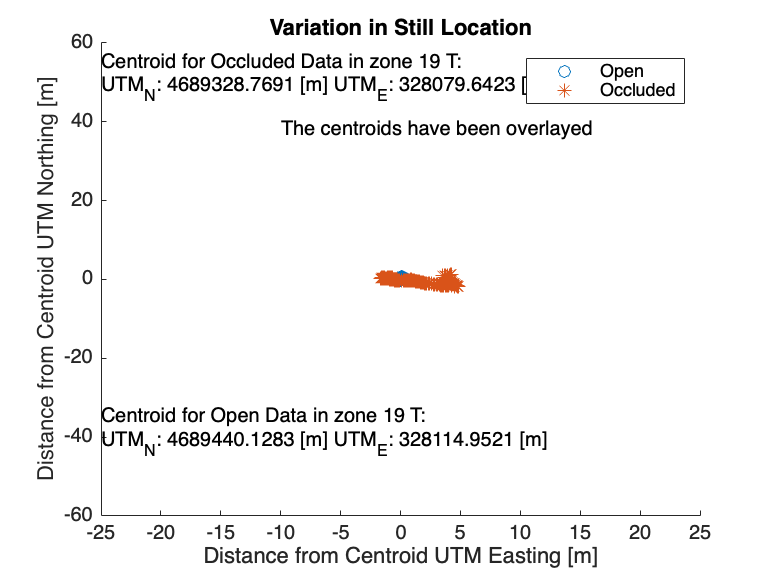


figure(1)

scatter(EastingPoints_op_dev,NorthingPoints_op_dev,"Marker","o")
hold on
scatter(EastingPoints_oc_dev,NorthingPoints_oc_dev,"Marker","*")
hold off
axis([-25 25 -60 60])
title('Variation in Still Location')
xlabel('Distance from Centroid UTM Easting [m]')
ylabel('Distance from Centroid UTM Northing [m]')
legend({'Open','Occluded'},'Location','northeast')

txt = {'Centroid for Occluded Data in zone 19 T:'};
text(-25,55,txt)
txt = ['UTM_N: ' num2str(centroid_oc(1)) ' [m]' ' UTM_E: ' num2str(centroid_oc(2)) ' [m]'];
text(-25,48,txt)

txt = {'Centroid for Open Data in zone 19 T:'};
text(-25,-35,txt)
txt = ['UTM_N: ' num2str(centroid_op(1)) ' [m]' ' UTM_E: ' num2str(centroid_op(2)) ' [m]'];
text(-25,-42,txt)


ftxt = {'The centroids have been overlayed'};
text(-10,38,ftxt)


%hold on
%plot(centroid_op,"LineWidth",4)
%hold on
%plot(centroid_oc,"LineWidth",4)

%%%%%%%%%%%%%%%%%%%%

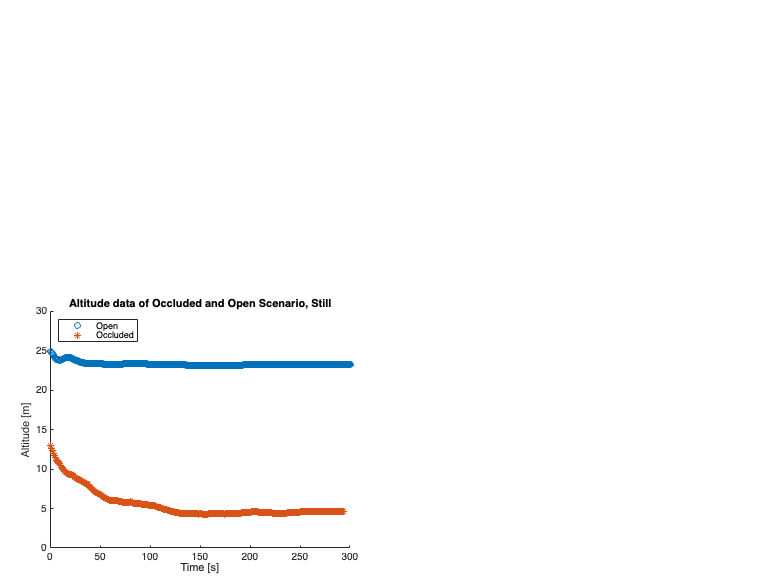


figure(2)

Time_op1 = Time_op-Time_op(1);
scatter(Time_op1,Alt_op,"Marker","o")
hold on
Time_oc1 = Time_oc-Time_oc(1);
scatter(Time_oc1,Alt_oc,"Marker","*")

axis([0 300 0 30])
title('Altitude data of Occluded and Open Scenario, Still')
xlabel('Time [s]')
ylabel('Altitude [m]')
legend({'Open','Occluded'},'Location','northwest')
hold off


%%%%%%%%%%%%%%%%%%%%%%%%


figure(3)

horizontal = linspace(0,50,50);
x1 = EastingPoints_walk-EastingPoints_walk(1);
y1 = NorthingPoints_walk-NorthingPoints_walk(1);
LBF = polyfit(x1,y1,1)

LBF =     1.0896   -0.1989


[p,S] = polyfit(x1,y1,1);
scatter(x1,y1,"Marker","*")
hold on
f = polyval(LBF,horizontal);
plot(horizontal,f)
R_squared = 1 - (S.normr/norm(y1 - mean(y1)))^2

R_squared = 0.9998

S

S = struct with fields:
        R: [2×2 double]
       df: 71
    normr: 1.8473


error = (LBF(1,1).*x1-LBF(1,2))-y1;

error =     0.1989
   -0.0372
   -0.0042
    0.0412
   -0.1028
    0.2500
    0.2978
    0.3952
    0.2531
    0.2600


error_avg = mean(abs(error))

error_avg = 0.4018

error_std = std(abs(error))

error_std = 0.2102

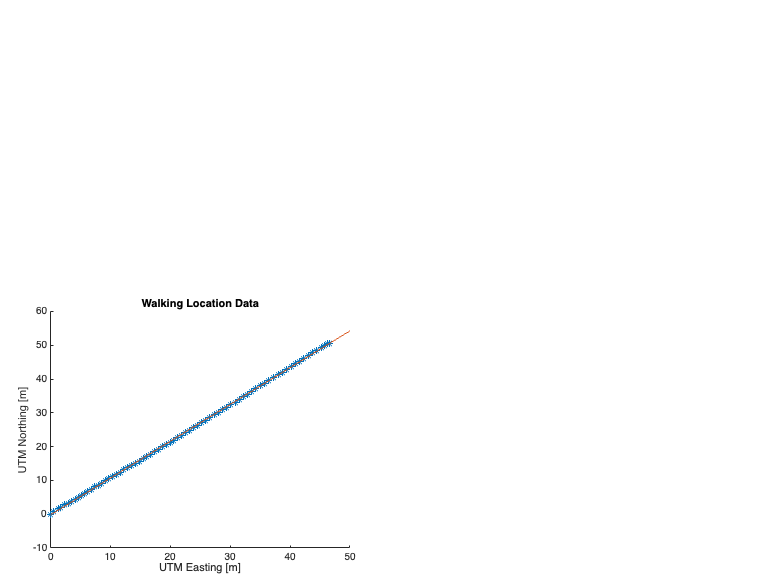


%set(l1(1),'color','magenta')
%plot(polyval(EastingPoints_walk_op1,LBF_op))

title('Walking Location Data')
xlabel('UTM Easting [m]')
ylabel('UTM Northing [m]')
%legend({'Walking','Walking Line of Best fit'},'Location','northwest')
hold off

%%%%%%%%%%%%%%%%%%

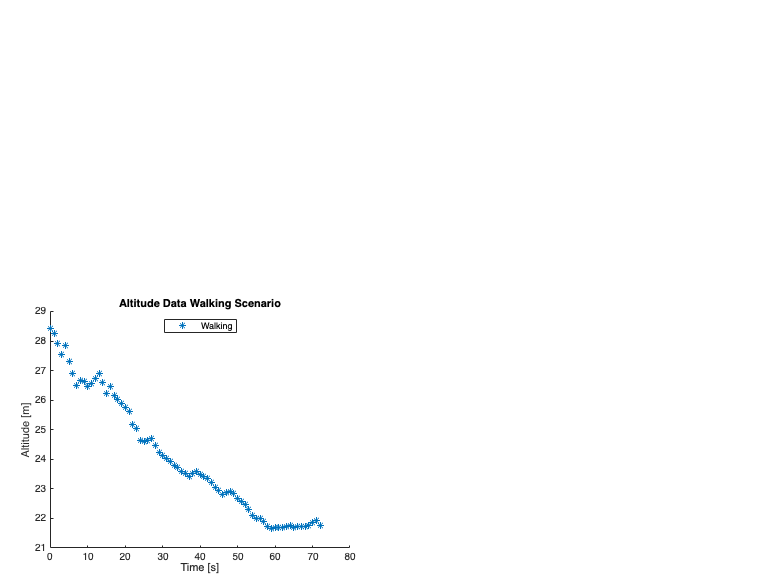

figure(4)

Time_walk = Time_walk-Time_walk(1);
scatter(Time_walk,Alt_walk,"Marker","*")
title('Altitude Data Walking Scenario')
xlabel('Time [s]')
ylabel('Altitude [m]')
legend({'Walking'},'Location','north')


%%%%%%%%%%%%%%%%%%%%

figure(5)
subplot(2,1,1); 
EC_open = sqrt(NorthingPoints_op_dev.^2+EastingPoints_op_dev.^2);
histogram(EC_open,50);
title('Euclidean Distance to centroid in Open Scenario, Still')
xlabel('Distance [m]')
ylabel('Instances')
m_op = mean(EC_open)

m_op = 0.1949

s_op = std(EC_open)

s_op = 0.1626

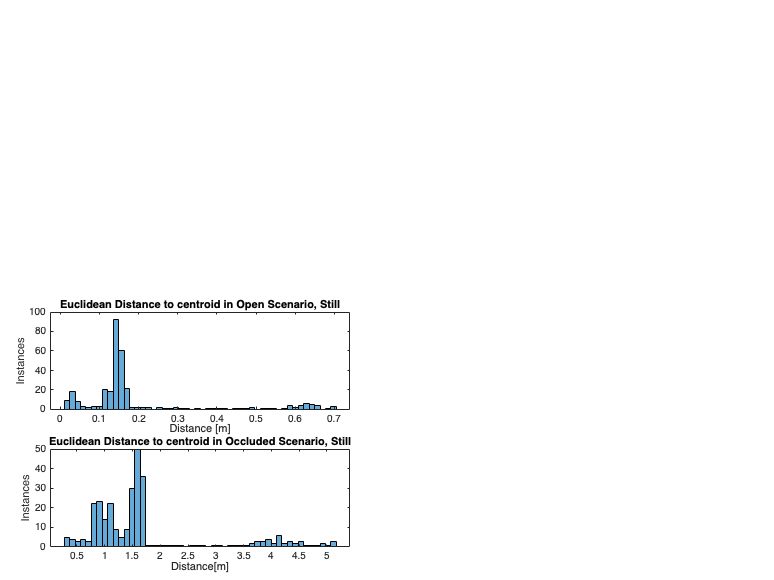


subplot(2,1,2);
EC_occluded = sqrt(NorthingPoints_oc_dev.^2+EastingPoints_oc_dev.^2); 
histogram(EC_occluded,50);
title('Euclidean Distance to centroid in Occluded Scenario, Still')
xlabel('Distance[m]')
ylabel('Instances')


m_oc = mean(EC_occluded)

m_oc = 1.7368

S_oc = std(EC_occluded)

S_oc = 1.1196